## Condiciones iniciales de arfada


syms a1(t) a2(t) a3(t) a4(t) a5(t) a6(t) a7(t) T A
syms v1(t) v2(t) v3(t) v4(t) v5(t) v6(t) v7(t) 
syms x1(t) x2(t) x3(t) x4(t) x5(t) x6(t) x7(t)
assume(T>0)
assume(A>0)
g=9.81;
xMax=0.1

xMax = 0.1000

aMax=g/2

aMax = 4.9050

A=aMax;

## Aceleración

a1(t)=9*A/T*t;

a2(t)=A;

a3(t)=-9*A/T*t;
Ca3=A-a3(2*T/9);
a3(t)=a3(t)+Ca3;

a4(t)=0;

a5(t)=-9*A/T*t;
Ca5=a4(2*T/3)-a5(2*T/3);
a5(t)=a5(t)+Ca5;

a6(t)=-A;

a7(t)=9*A/T*t;
Ca7=a6(8*T/9)-a7(8*T/9);
a7(t)=a7(t)+Ca7;
fprintf('Función de aceleración:')

Función de aceleración:

a(t)=piecewise((0<=t<T/9),a1,(T/9<=t<2*T/9),a2,(2*T/9<=t<T/3),a3,(T/3<=t<2*T/3),a4,(2*T/3<=t<7*T/9),a5,(7*T/9<=t<8*T/9),a6,(8*T/9<=t<T),a7)

$$a(t) = \begin{array}{l} \left\{ \begin{array}{cl} \sigma_{1} & \text{ if }9\,t<T\wedge 0\leq t\\ \frac{981}{200} & \text{ if }T\leq 9\,t\wedge 9\,t<2\,T\\ \frac{2943}{200}-\sigma_{1} & \text{ if }3\,t<T\wedge 2\,T\leq 9\,t\\ 0 & \text{ if }T\leq 3\,t\wedge 3\,t<2\,T\\ \frac{2943}{100}-\sigma_{1} & \text{ if }9\,t<7\,T\wedge 2\,T\leq 3\,t\\ -\frac{981}{200} & \text{ if }9\,t<8\,T\wedge 7\,T\leq 9\,t\\ \sigma_{1}-\frac{8829}{200} & \text{ if }t<T\wedge 8\,T\leq 9\,t \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{8829\,t}{200\,T} \end{array}$$

## Velocidad

v1(t)=int(a1);

v2(t)=int(a2);
Cv2=v1(T/9)-v2(T/9);
v2(t)=v2(t)+Cv2;

v3(t)=int(a3);
Cv3=v2(2*T/9)-v3(2*T/9);
v3(t)=v3(t)+Cv3;

v4(t)=v3(T/3);

v5(t)=int(a5);
Cv5=v4(2*T/3)-v5(2*T/3);
v5(t)=v5(t)+Cv5;

v6(t)=int(a6);
Cv6=v5(7*T/9)-v6(7*T/9);
v6(t)=v6(t)+Cv6;

v7(t)=int(a7);
Cv7=v6(8*T/9)-v7(8*T/9);
v7(t)=v7(t)+Cv7;
fprintf('Función de velocidad:')

Función de velocidad:

v(t)=piecewise((0<=t<T/9),v1,(T/9<=t<2*T/9),v2,(2*T/9<=t<T/3),v3,(T/3<=t<2*T/3),v4,(2*T/3<=t<7*T/9),v5,(7*T/9<=t<8*T/9),v6,(8*T/9<=t<T),v7)

$$v(t) = \begin{array}{l} \left\{ \begin{array}{cl} \frac{8829\,t^{2}}{400\,T} & \text{ if }9\,t<T\wedge 0\leq t\\ \frac{981\,t}{200}-\frac{109\,T}{400} & \text{ if }T\leq 9\,t\wedge 9\,t<2\,T\\ -\frac{109\,T}{80}-\frac{t\,\left(\sigma_{1}-2943\right)}{200} & \text{ if }3\,t<T\wedge 2\,T\leq 9\,t\\ \frac{109\,T}{100} & \text{ if }T\leq 3\,t\wedge 3\,t<2\,T\\ -\frac{218\,T}{25}-\frac{t\,\left(\frac{8829\,t}{4\,T}-2943\right)}{100} & \text{ if }9\,t<7\,T\wedge 2\,T\leq 3\,t\\ \frac{1853\,T}{400}-\frac{981\,t}{200} & \text{ if }9\,t<8\,T\wedge 7\,T\leq 9\,t\\ \frac{8829\,T}{400}+\frac{t\,\left(\sigma_{1}-8829\right)}{200} & \text{ if }t<T\wedge 8\,T\leq 9\,t \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{8829\,t}{2\,T} \end{array}$$

## Desplazamiento


x1(t)=int(v1);

x2(t)=int(v2);
Cx2=x1(T/9)-x2(T/9);
x2(t)=x2(t)+Cx2;

x3(t)=int(v3);
Cx3=x2(2*T/9)-x3(2*T/9);
x3(t)=x3(t)+Cx3;

x4(t)=int(v4);
Cx4=x3(T/3)-x4(T/3);
x4(t)=x4(t)+Cx4;

x5(t)=int(v5);
Cx5=x4(2*T/3)-x5(2*T/3);
x5(t)=x5(t)+Cx5;

x6(t)=int(v6);
Cx6=x5(7*T/9)-x6(7*T/9);
x6(t)=x6(t)+Cx6;

x7(t)=int(v7);
Cx7=x6(8*T/9)-x7(8*T/9);
x7(t)=x7(t)+Cx7;

fprintf('Función de desplazamiento:')

Función de desplazamiento:

x(t)=piecewise((0<=t<T/9),x1,(T/9<=t<2*T/9),x2,(2*T/9<=t<T/3),x3,(T/3<=t<2*T/3),x4,(2*T/3<=t<7*T/9),x5,(7*T/9<=t<8*T/9),x6,(8*T/9<=t<=T),x7)

$$x(t) = \begin{array}{l} \left\{ \begin{array}{cl} \sigma_{1} & \text{ if }9\,t<T\wedge 0\leq t\\ \frac{109\,T^{2}}{10800}-\frac{109\,t\,\left(T-9\,t\right)}{400} & \text{ if }T\leq 9\,t\wedge 9\,t<2\,T\\ \frac{109\,T^{2}}{1200}-\frac{109\,t\,\left(5\,T^{2}-27\,T\,t+27\,t^{2}\right)}{400\,T} & \text{ if }3\,t<T\wedge 2\,T\leq 9\,t\\ \frac{109\,T\,t}{100}-\frac{109\,T^{2}}{600} & \text{ if }T\leq 3\,t\wedge 3\,t<2\,T\\ \frac{1199\,T^{2}}{600}-\frac{218\,T\,t}{25}+\frac{2943\,t^{2}}{200}-\sigma_{1} & \text{ if }9\,t<7\,T\wedge 2\,T\leq 3\,t\\ \frac{109\,t\,\left(17\,T-9\,t\right)}{400}-\frac{3161\,T^{2}}{2160} & \text{ if }9\,t<8\,T\wedge 7\,T\leq 9\,t\\ \frac{2943\,t\,\left(3\,T^{2}-3\,T\,t+t^{2}\right)}{400\,T}-\frac{7957\,T^{2}}{1200} & \text{ if }t\leq T\wedge 8\,T\leq 9\,t \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{2943\,t^{3}}{400\,T} \end{array}$$

## Solución de tMax

f=xMax/2==x(T/2);

tMax=solve(f,T);


a=subs(a,T,tMax);
v=subs(v,T,tMax);
x=subs(x,T,tMax);

fprintf('Tiempo de ciclo %.3f s',tMax)

Tiempo de ciclo 0.371 s

## Gráficas

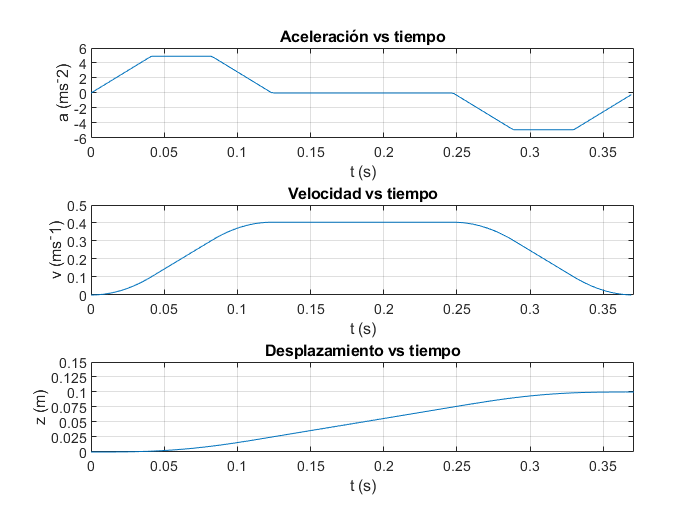

ts=linspace(0,tMax,200);

subplot(3,1,1)

plot(ts,a(ts))
title('Aceleración vs tiempo')
grid on
xlabel('t (s)')
ylabel('a (ms^-2)')
ylim([-6 6])
xlim([0 double(tMax)])
yticks(-6:2:6)


subplot(3,1,2)

plot(ts,v(ts))
title('Velocidad vs tiempo')
grid on
xlabel('t (s)')
ylabel('v (ms^-1)')
ylim([0 0.5])
xlim([0 double(tMax)])
yticks(0:0.1:0.5)

subplot(3,1,3)

plot(ts,x(ts))
title('Desplazamiento vs tiempo')
grid on
xlabel('t (s)')
ylabel('z (m)')
ylim([0 0.15])
xlim([0 double(tMax)])
yticks(0:0.025:0.15)

## Cinetica Arfada

W=480*9.81

W = 4.7088e+03

Wp=43*9.81

Wp = 421.8300

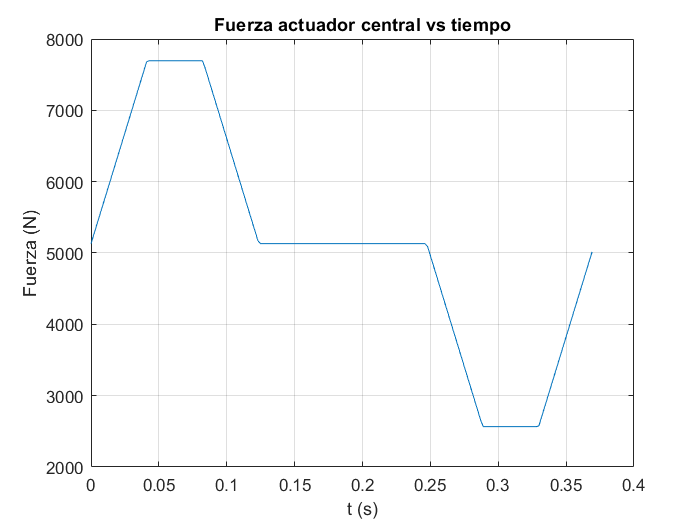


Fa=(43+480)*a+W+Wp;
figure()
plot(ts,Fa(ts))
grid on
title('Fuerza actuador central vs tiempo')
xlabel('t (s)')
ylabel('Fuerza (N)')